# Unit 4.3: LTI Systems for Differential Equations

## Example 8.1

The continuous-time system shown below consists of one integrator and one scalar multiplier. Write and solve the differential equation that relates the output 𝑦(𝑡) to the input 𝑥(𝑡).

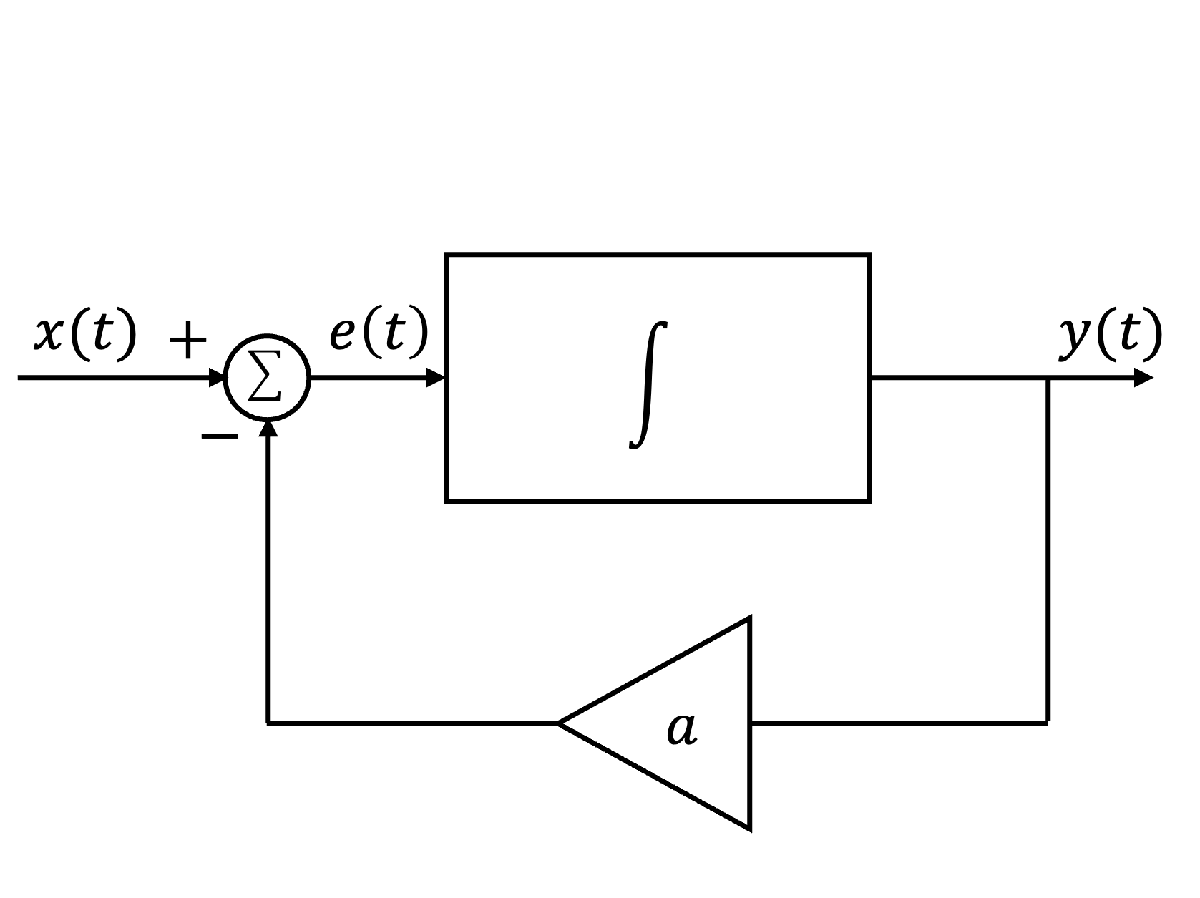

A one integrator system

clear vars

In the symbolic math toolbox, we can solve continuous-time LTI systems using `dslove`

% doc dsolve

We first need to define our symbolic variables

syms t y(t) a
u0(t) = heaviside(t); % It's quicker and more readable to type u0(t)

Le's make the input a delayed unit step

x(t) = u0(t);

Define the differential equation with assumptions and initial conditions

ode = diff(y(t),t)+a*y(t)==x(t)
assume(a > 0);
dsolve(ode)

Solution depends on the initial value of $y(t)$ so let's define $y(0)=0$ using a condition

cond = y(0) == 0;

Resolve the equation

y(t) = dsolve(diff(y(t),t)+a*y(t)==x(t),cond)

Note MATLAB uses `(sign(t) - 1)/2` rather than `heaviside(t)`

aval = 2
fplot([x(t),subs(y(t),a,aval)],[0,10]),grid,ylim([0,1.2]),...
   title('Solution of dy(t)/dt + y(t) = u_0(t)'),...
   ylabel('t'),...
   legend('x(t)','y(t)')

### **Simulation**

We can also exploit the MATLAB simulation tool Simulink to solve this equation directly from the block diagram.

example8_1

## Example 8.2

The continuous-time system shown below consists of two integrators and two scalar multipliers. Write and solve the differential equation that relates the output 𝑦(𝑡) to the input 𝑥(𝑡).

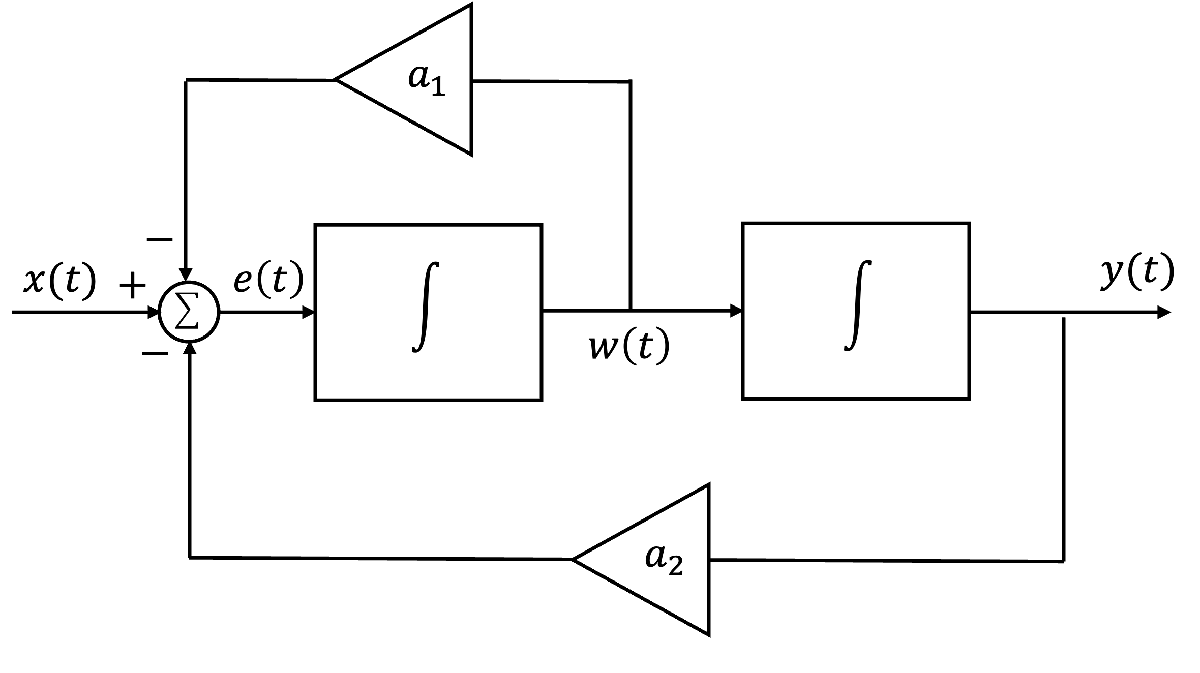

clear y(t)
syms y(t) a_1 a_2
assume([a_1 > 0, a_2> 0])


dy(t) = diff(y(t),t);
d2y(t) = diff(y(t),t,2);
ode2 = d2y(t) + a_1*dy(t) + a_2*y(t)==x(t)

Solve this

dsolve(ode2)

Final result depends on $C_1$ and $C_2$ which are defined by the initial values of $y(t)$ and $dy(t)/dt$. So let's define these as $dy(0)/dt = 0$ and $y(0)=0$ using a *condition*

cond = [y(0) == 0,dy(0) == 0];

And resolve the ODE

dsolve(ode2,cond)

The equation cannot be found because the solution depends on the actual values of $a_1$ and $a_2$.

Let's let $a_2=9$ and let's vary $a_1$ and find the solution using Simulink

a2 = 9;
a1 = 0.7;
ode2 = d2y(t)+a1*dy(t)+a2*y(t) == x(t);

dy

sol = dsolve(ode2,cond);
fplot(sol,[0,10]),grid,...
   title('Solution of d^2y(t)/dt^2 + a1*dy(t)/dt + a2*y(t) = u_0(t)'),...
   ylabel('t')

### Simulation

example8_2

`In [50]:`